## Ejercicio 1: considere el robot planar de 2 g.d.l. de la siguiente figura:

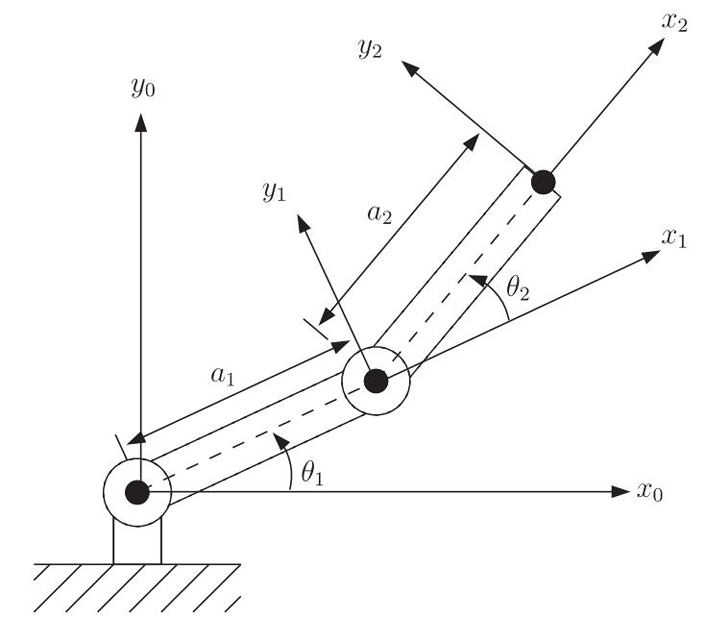

Se puede determinar que la cinemática directa está dada por:


$$x = a_1 cos(\theta_1) + a_2 cos(\theta_1+\theta_2)$$



$$y = a_1 sen(\theta_1) + a_2 cos(\theta_1+\theta_2)$$



$$z = 0$$



$$\alpha
 = 0$$



$$\beta = 0$$



$$\gamma = \theta_1+\theta_2$$


Estas ecuaciones se pueden hallar geométricamente o mediante el análisis de la  transformación ${}^{0}T_2$ que surge de aplicar DH (es necesario convertir ángulos).

Mediante el método geométrico se puede hallar un sistema para la cinemática inversa  correspondiente a la formulación $\overline{q}= f (x,y,z)$:


$$\theta_1= atan2(x-a_2sin(\gamma), x-s_2cos(\gamma))$$



$$\theta_2 =\gamma -\theta_1$$


1. Mediante derivación respecto del tiempo obtenga el Jacobiano del robot que  corresponde a:


$$\dot{p}=J(q)\dot{q}$$


Donde:

- 
$$\dot{p}=[\dot{x}\quad\dot{y}\quad\dot{z}\quad\dot{\alpha}\quad\dot{\beta}\quad\dot{\gamma}]^T$$


- 
$$q = [\theta_1\quad\theta_2]^T$$


2. Calcule la velocidad del extremo $\dot{p}$ , en $m/s$  para $q=[\pi/6\quad\pi/6]$, en 𝑟𝑎𝑑 y $\dot{q}=[0\quad-1]$ en 𝑟𝑎𝑑/𝑠. Suponga longitud de eslabón unitaria. Observe el gráfico del robot  e interprete los resultados.

3. Trabaje solo con las coordenadas X-Y (primeras 2 filas del $J$) y verifique mediante la  inversa algebraica que $\dot{q} = J^{-1}(q)\dot{p}$ se cumple.

## Ejercicio 2: halle el Jacobiano en forma general de los 3 robots siguientes: 

1.

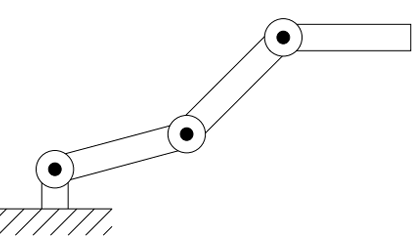

2.

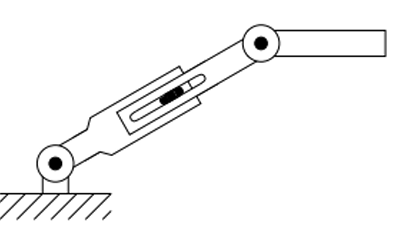

3.

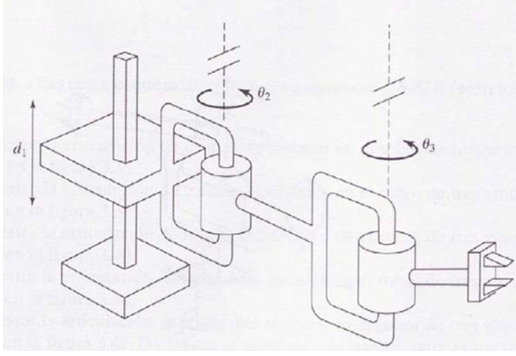

## Ejercicio 3: el siguiente código de ejemplo se puede utilizar para obtener el Jacobiano del  ejercicio 1 de forma general. Haga los cambios necesarios para verificar los resultados del  ejercicio 2. Tenga en cuenta que con las identidades trigonométricas se puede cambiar  radicalmente una misma expresión.

syms q1 q2 a1 a2 real 
q = [q1 q2]; 
dh = [0,0,a1,0,0; 
0,0,a2,0,0]; 
R = SerialLink(dh); 
J = simplify(R.jacob0(q)); 
disp(J)

## Ejercicio 4: agregando el código siguiente al código anterior, se puede observar una expresión  simplificada del determinante del Jacobiano del mismo robot. Es importante recordar que una  matriz cuadrada tiene inversa únicamente si su determinante es distinto de cero.

Jr = J(1:2,:); 
DJr = simplify(det(Jr)); 
disp(DJr)

- 1. Determine para qué valores de $q = [\theta_1\quad\theta_2]^T$ será cero el determinante.

- 2. Interprete qué tienen de particular las soluciones del punto anterior.

## Ejercicio 5:  trabaje con el primer robot del ejercicio 2: 

1) Adapte el código anterior para analizar el Jacobiano simbólico y halle la expresión del  determinante. ¿Puede aplicar los puntos 1 y 2 del ejercicio anterior? 

2) Trabaje numéricamente con longitud de eslabón 1m, 0.8m y 0.6m. Calcule el Jacobiano  y su determinante para $q=[\pi/6\quad\pi/6]$, en 𝑟𝑎𝑑. Verifique que el determinante  es cero. Verifique que el rango de la matriz es menor que los g.d.l. del robot (función  “rank”). Ejecute la función “jsingu(J)” e interprete y relacione el resultado con el robot  del ejercicio 1.

3) Para la posición articular anterior:  

a. Calcule la velocidad articular requerida para lograr las siguientes velocidades  cartesianas en el extremo operativo:$v=[1\quad0\quad0]$ en 𝑚/𝑠. Use el jacobiano  reducido.

b. ¿Por qué existe inversa?

c. ¿Cuál es el número de condición del jacobiano reducido?

d. Asuma que $q_2$ no es cero, sino que está cerca: $q_2 = 0,001$. ¿Cuánto valen las  velocidades articulares para lograr el mismo $v$? 

e. ¿Cuánto valen el determinante y el número de condición del jacobiano en este  caso?

f.  ¿Qué conclusión puede sacar sobre la proximidad del punto singular?

# Ejercicio TF (obligatorio): trabaje con su robot:

Trate de hallar el jacobiano y el determinante simbólico de su robot.  Intente determinar los puntos singulares a partir del determinante simbólico. En caso de que  no se puedan calcular (expresiones muy extensas), identifique al menos 3 mediante  observaciones y análisis, y verifique que el determinante sea nulo en esos casos.  Estudie si en la aplicación elegida se trabajará en las proximidades de algún punto singular.